Leighton Clarke

Advanced Protections, Take-home Exam 2

May 26, 2018

# Problem 1

## 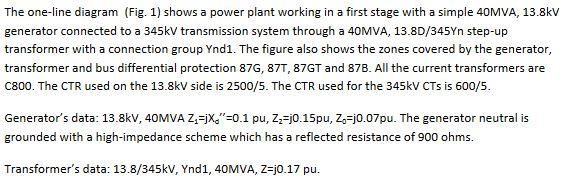

## Parts 1.1 and 1.2

The diagram has been completed and attached on the following page. The first step to solving for all of the currents is to calculate the nominal primary line current magnitudes, Ip and Iq.

j = sqrt(-1);
S = 40e6;
VHigh = 345e3;
VLow = 13.8e3;
CTR1 = 2500/5;
CTR2 = 600/5;

Ip = S/(sqrt(3)*VLow);
fprintf('Low side primary current: %f A',Ip)

Low side primary current: 1673.479041 A

Iq = S/(sqrt(3)*VHigh);
fprintf('High side primary current: %f A',Iq)

High side primary current: 66.939162 A

We can divide the primary currents by the CTRs to get the secondary currents, I1 and I2. Because the high-side CTs are arranged in a delta configuration, we must multiply those secondary currents by the square root of 3.

I1 = Ip/CTR1;
fprintf('Low side secondary current: %f A',I1)

Low side secondary current: 3.346958 A

I2 = Iq/CTR2 * sqrt(3);
fprintf('High side secondary current: %f A',I2)

High side secondary current: 0.966184 A

Now that the magnitudes have been determined, we must apply the appropriate angles. This is a Ynd1 transformer, which means that the low-side voltages lag the high-side voltages by 30 degrees. We can show this mathematically as well by observing which lines are connected in the delta configurations:


$$I_a -I_c =|I|\angle 0^{\circ } -|I|\angle {120}^{\circ } =\sqrt{3}|I|\angle -{30}^{\circ }$$



$$I_b -I_a =|I|\angle {-120}^{\circ } -|I|\angle 0^{\circ } =\sqrt{3}|I|\angle -{150}^{\circ }$$



$$I_c -I_b =|I|\angle {120}^{\circ } -|I|\angle {-120}^{\circ } =\sqrt{3}|I|\angle {90}^{\circ }$$


These angles have been added to the attached system diagram.

## Part 1.3

The simplest option is to round each secondary current magnitude up to the nearest available tap.

Tap1 = 3.4;
Tap2 = 1.0;
M = abs(I1/Tap1-I2/Tap2)/(I2/Tap2) * 100;
fprintf('Taps chosen using general estimation: Tap 1 = %g A; Tap 2 = %g A',Tap1,Tap2)

Taps chosen using general estimation: Tap 1 = 3.4 A; Tap 2 = 1 A

fprintf('Mismatch using estimation: %f%%', M)

Mismatch using estimation: 1.885342%

Because the goal of tapping is to minimize the mismatch under normal operating conditions, a better option is to test every combination of taps to find values yielding the lowest possible mismatch:

Tap = 1:0.1:20;
Marray = zeros(length(Tap));
for k = 1:length(Tap)
    for n = 1:length(Tap)
        Marray(k,n) = abs(I1/Tap(k)-I2/Tap(n))/(I1/Tap(k)) * 100;
    end
end
Mmin = min(Marray(:));
[row,col]=find(Marray==Mmin);
fprintf('Taps for minimal mismatch: Tap 1 = %g A; Tap 2 = %g A',Tap(row(1)),Tap(col(1)))

Taps for minimal mismatch: Tap 1 = 19.4 A; Tap 2 = 5.6 A

fprintf('Minimum possible mismatch: %f%%',Mmin)

Minimum possible mismatch: 0.005314%

# Problem 2

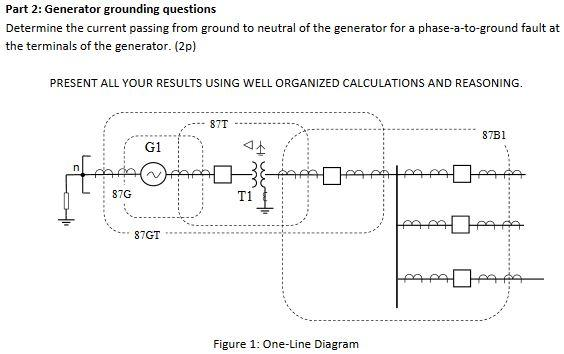

According to the information given in problem 1, the equivalent resistance of the grounding scheme is 900 ohms. The ground-to-neutral current for a single phase fault is calculated from the grounding resistance and the induced phase voltage.

Vp = 13.8e3/sqrt(3);
Rgn = 900;
Ign = Vp/Rgn;
fprintf('Ground to neutral current for a phase fault: %f A',Ign)

Ground to neutral current for a phase fault: 8.852704 A

# Problem 3

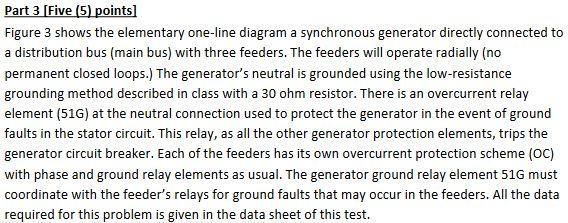

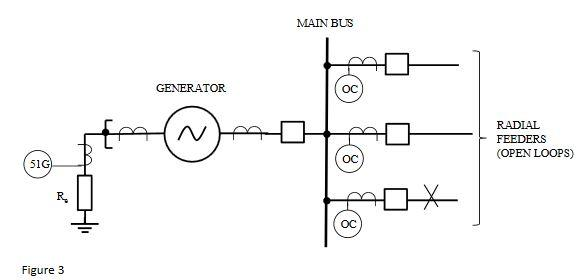

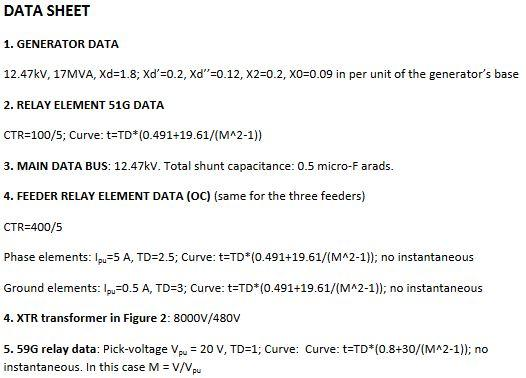

## Part a

First we must calculate the rated current. Then we can transfer 10% of that current across the CTR.

VL = 12.47e3;
S = 17e6;
Irated = S/(sqrt(3)*VL);
CTR = 100/5;
Irelay = Irated*0.1/CTR

Irelay = 3.9354

The next available pick-up current setting is 4 A.

Ipu = 4;
fprintf('51G pick-up setting for 10%% of rated current : %g A',Ipu)

51G pick-up setting for 10% of rated current : 4 A

## Part b

The grounding resistance has been provided as 30 ohms. For low-resistance grounding schemes, we assume the current for a single-phase fault at the feeder relay will be nearly equal to the current at the generator. Therefore we can simply divide the generator voltage by the grounding impedance.

Re = 30;
If = VL/sqrt(3)/Re

If = 239.9853

We can now calculate the operating time for the feeder relay for this fault current.

TD_feeder = 3;
CTR_feeder = 400/5;
Ipu_feeder = 0.5;
M_feeder = If/(CTR_feeder*Ipu_feeder);
top_feeder = TD_feeder*(0.491+19.61/(M_feeder^2-1));
fprintf('Feeder relay operation time: %f s',top_feeder)

Feeder relay operation time: 3.154070 s

Ideally the 51G relay will operate 0.4 seconds after the feeder relay. We can use this time to calculate the TD with the other provided and calculated settings.

M_51G = If/(CTR*Ipu);
TD_51G = (top_feeder+0.4)/(0.491+19.61/(M_51G^2-1))

TD_51G = 1.2078

This is very close to an available TD setting, so we round to 1.2

TD = 1.2;
fprintf('51G TD setting for coordination with feeder relays: %g',TD)

51G TD setting for coordination with feeder relays: 1.2

# Problem 4

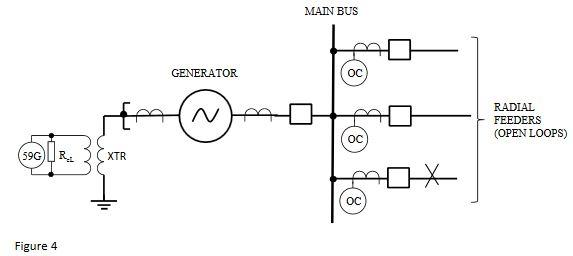

## Part a

Given the generator voltage and neutral-to-ground current, we can calculate the equivalent resistance, and then find the value of the resistor on the other side of the transformer.

IR = 8;
ReH = VL/sqrt(3)/IR;
XTR = 8000/480;
ReL = ReH/XTR^2;
fprintf('Low voltage resistor value: %f ohms',ReL)

Low voltage resistor value: 3.239801 ohms

## Part b

Power dissipation in a resistor is given by the equation $P=\frac{V^2 }{R}$. The full generator voltage is dropped across the reflected impedance, so we can transfer this across the transformer to find the voltage across the actual resistor.

VHigh = VL/sqrt(3);
VLow = VHigh/XTR;
PDis = VLow^2/ReL;
fprintf('Power dissipated in resistor for given fault conditions: %f kW',PDis/1000)

Power dissipated in resistor for given fault conditions: 57.596463 kW

## Part c

The voltage across the relay has already been calculated, and the settings are all provided. The operation time can be calculated directly.

Vpu = 20;
M_59G = VLow/Vpu;
top_59G = 1*(0.8+30/(M_59G^2-1));
fprintf('Operation time of 59G relay for given fault conditions: %f s',top_59G)

Operation time of 59G relay for given fault conditions: 0.864446 s

## Part d

For a high resistance grounding scheme with non-negligible shunt capacitance, we know that the fault current is given by:


$$I_f =I_R +I_{\mathrm{gb}} +I_{\mathrm{cg}}$$


where $I_{\mathrm{gb}} +I_{\mathrm{cg}} =j\cdot I_R$ so that the fault current has an angle of 45 degrees, i.e. $I_f =I_R +j\cdot I_R$. We can calculate the secondary current detected at the feeder relay for these fault conditions:

If = IR + j*IR;
I_relay = If/CTR_feeder;
fprintf('Current magnitude at feeder relay: %f A',abs(I_relay))

Current magnitude at feeder relay: 0.141421 A

The fault current detected by the feeder relay is lower than the pick-up setting. This means that the feeder relay will never operate for this type of fault, making coordination with the generator protection impossible. Because the generator 59G relay will operate, all feeders will lose power in the event of a close-in ground fault. If the feeder relay pick-up settings were lowered, it would be possible to first isolate the faulted feeder before the generator protection operated. Therefore, it is important to consider generator grounding schemes when setting feeder relays, because different ground schemes result in very different current magnitudes.